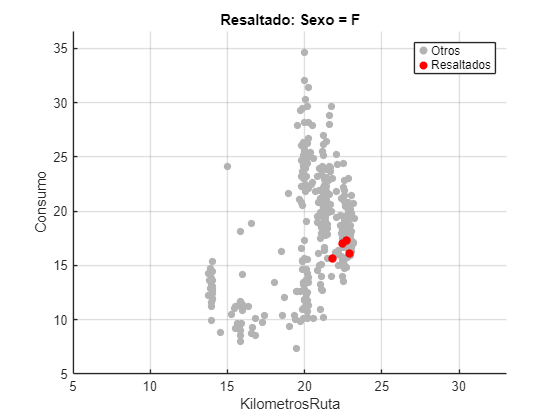

% Definición de los ejes y características a resaltar
ejeX = 'KilometrosRuta';
ejeY = 'Consumo';


idx_todo = ~isnan(Tabla.(ejeX)) & ~isnan(Tabla.(ejeY));
idx_resaltado = idx_todo & strcmp(Tabla.('Sexo'), "H")...
& idx_todo & strcmp(Tabla.('NombreRuta'), "A601");

figure;
hold on;
scatter(Tabla.(ejeX)(idx_todo & ~idx_resaltado), Tabla.(ejeY)(idx_todo & ~idx_resaltado), 30, [0.7 0.7 0.7], 'filled'); % Gris para "otros"
scatter(Tabla.(ejeX)(idx_resaltado), Tabla.(ejeY)(idx_resaltado), 40, 'r', 'filled'); % Rojo para los resaltados
hold off;
xlabel(ejeX);
ylabel(ejeY);
title(sprintf('Resaltado: %s = %s', caracteristica, valor_resaltar));
legend('Otros','Resaltados');
grid on;

xlim([5.0 33.1])
ylim([5.0 36.6])